# Kane-Mele Model / Spin Hall Effect

This note is used to calculate **spin hall effect**


$$H=\sum_{\langle ij\rangle \alpha}tc_{i\alpha}^\dag c_{j\alpha}+\sum_{\langle\langle ij\rangle\rangle \alpha\beta}i\lambda_{so} (\hat{d}_{ik}\times\hat{d}_{kj})s^z_{\alpha\beta}c^\dag_{i\alpha}c_{j\beta}+i\lambda_R\sum_{<ij>}c_i^\dag(s\times d)c_j+\lambda_v\sum_i\epsilon_i c_i^\dag c_i$$


where the first term and third term are both nearest neighbour hoppping, but the later represents the Rashba spin-orbit coupling (SOC), the second term is intrinsic SOC  and the last term is on-site energy with $\epsilon_i =\pm 1$ for A/B sublattice.

## Model Construction

function syst = Kane_mele_Model(options)
% KANE_MELE_MODEL construct a model-syst for kane-mele model

arguments
    options.t = 1;
    options.lam_so (1,1);   % intrinsic SOC
    options.lam_v  (1,1);   % on-site energy
    options.lam_R  (1,1);   % Rashba SOC that breaks the time reversal symmetry
    options.Translation = [1,0;0,1]; % The translation symmetry direction
    options.Ns = 5;
    options.disorder = 0;
end
t = options.t; lam_so = options.lam_so; lam_R=options.lam_R; lam_v = options.lam_v;
Ns = options.Ns;
sx = [0,1;1,0]; sy = [0,-1i;1i,0];  sz = [1,0;0,-1];
vec = [-sqrt(3)/2 , 3/2; sqrt(3)/2,3/2];
basis = [0,0;0,1];
name = ["A","B"];
lat = TB_Hamilton.general(vec,name,basis,[2,2]);

lat.shape = polyshape(Ns*[0,-2*sqrt(3),0,2*sqrt(3),0],Ns*[0,6,12,6,0]-ones(1,5)*.5);
syst = TB_Hamilton.Builder(lat,options.Translation);
lats = lat.sublattice;
% on-site
function U = disorder(~,~,A,lam_v)
    U = A * (rand(1)-.5)*eye(2) + lam_v*eye(2);
end
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,0])) = @(x,y) disorder(x,y,options.disorder,lam_v);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[0,0])) = @(x,y) disorder(x,y,options.disorder,-lam_v);


% nearest hopping
d = lats{2}.pos([0,0]) - lats{1}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{2},[0,0])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));

d = lats{1}.pos([0,1]) - lats{2}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{1},[0,1])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));

d = lats{1}.pos([1,0]) - lats{2}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{1},[1,0])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));


% next nearest hopping
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[1,0])) = -1i*lam_so*sz;  
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,1])) = 1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[-1,1])) = -1i*lam_so*sz;

syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[1,0])) = 1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[0,1])) = -1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[-1,1])) = 1i*lam_so*sz;
syst.finalized;
end

## Show the lattice and reciprocal lattice

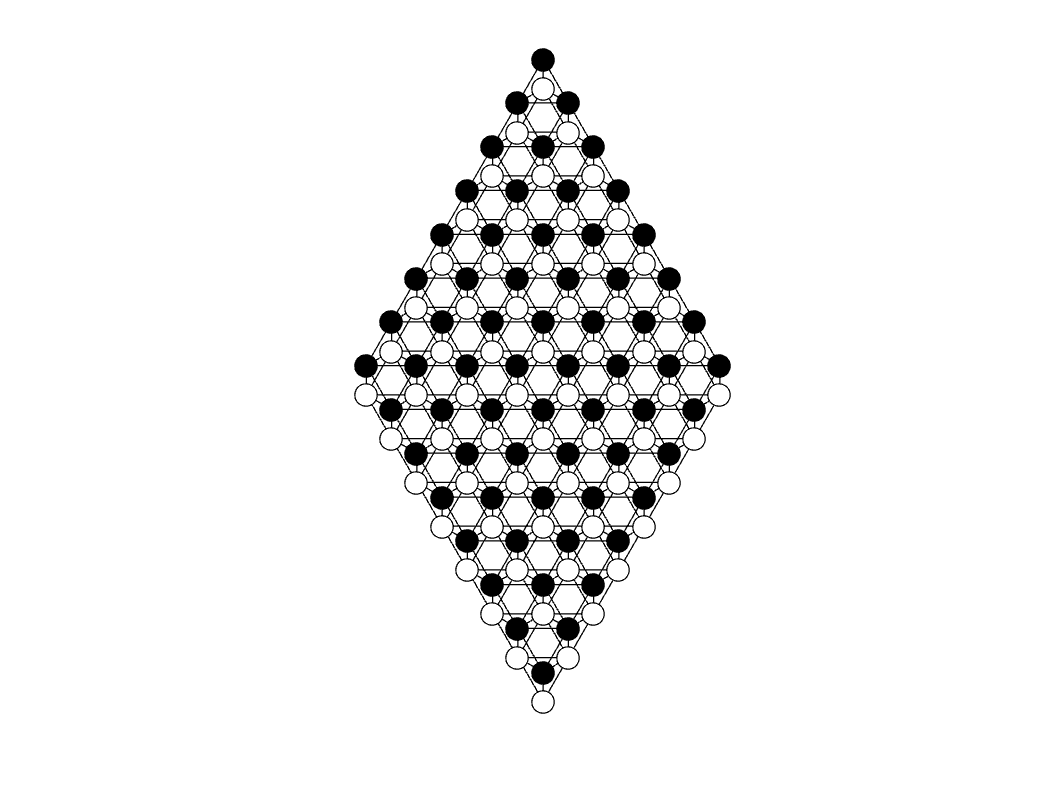

syst = Kane_mele_Model(lam_so = .06,lam_v = .4,lam_R = 0.05,Ns = 2,Translation = []);
figure
TB_Hamilton.Plot.ScatterRegion(syst,MarkerFaceColor=["w","k"],SizeData=80,MarkerEdgeColor='k')
axis off

### Reciprocal Lattice

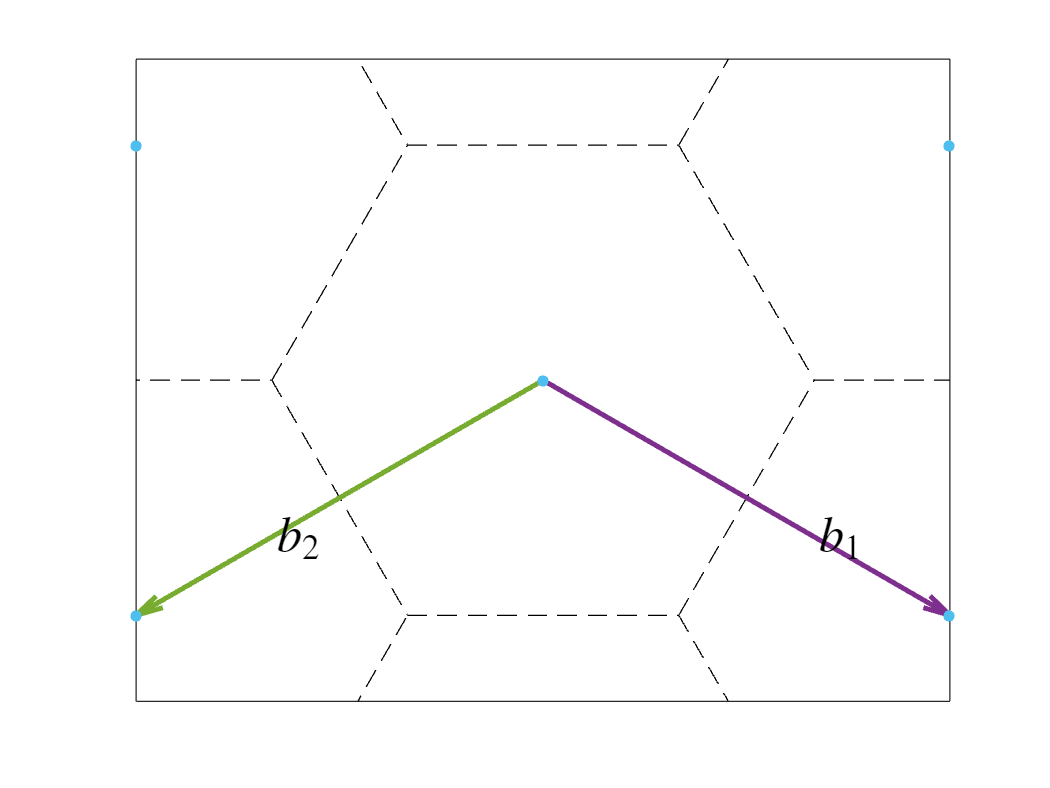

% axis off
figure
TB_Hamilton.Plot.FBZ(syst)

## Time Reversal Symmetry

This section is used to show the syst preserved the time reversal symmetry. Becase the exitence of spin, we have $\mathcal{T}=i\sigma_y K=\textrm{TK}$, where $K$ is a conjugate operator, $\sigma_y$ is a pauli matrix operators on spin space and $T$ is the unitary part.


$$\mathcal{T}H(k_x,k_y)\mathcal{T}^{-1}=TK\circ H(k_x,k_y)\circ KT^\dag=TH^*(k_x,k_y)T^\dag=H(-k_x,-k_y)$$


syst = Kane_mele_Model(lam_so = .06,lam_v = .4,lam_R = 0.1,Ns = 2); % bulk system
syst.system_graph.Nodes     % the subscripts 1 and 2 are spin up and down

ans = 4×1 table
        Name    
    ____________

    {'A(3,3)_1'}
    {'A(3,3)_2'}
    {'B(3,3)_1'}
    {'B(3,3)_2'}


where the subscript 1 and 2 represent the spin up and down.

sy = [0,-1i;1i,0];
T = 1i*kron(eye(2),sy); % the unitary part of T
syms kx ky real;
H = syst.Hamilton(kx,ky);
T*conj(H)*T'-syst.Hamilton(-kx,-ky) % the time reversal is preserved

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

## Band Energy

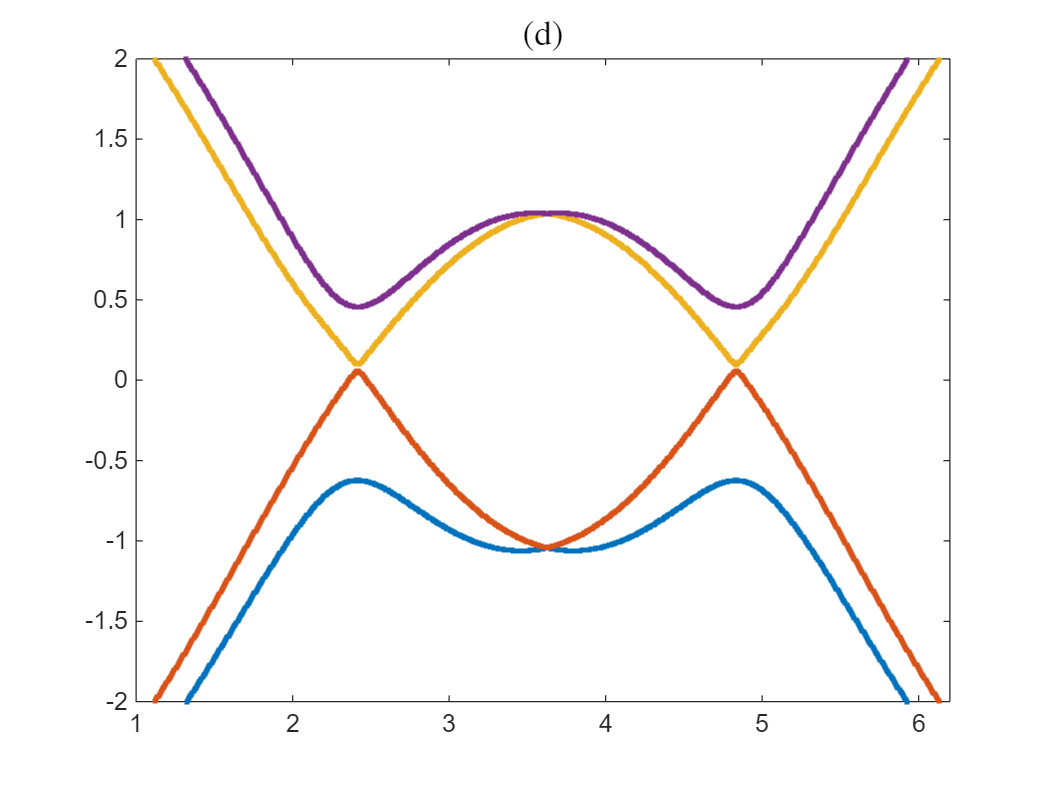

syst = Kane_mele_Model(lam_so = .05,lam_v = .2,lam_R = .1,Ns = 1);
kx = linspace(0,7.2,1000); ky = 0; num = 4;
Es = zeros(num,length(kx));
for j1 = 1:length(kx)
    H = full(syst.Hamilton(kx(j1),ky));
    Es(:,j1) = eig(H);
end
% nexttile(t,4)
figure
plot(kx,Es,'.','LineWidth',1)
ylim([-2,2]);xlim([1,6.2])
title('$\textrm{(d)}$','FontSize',14,'Interpreter','latex');

syst.system_graph.Nodes

ans = 4×1 table
        Name    
    ____________

    {'A(1,1)_1'}
    {'A(1,1)_2'}
    {'B(1,1)_1'}
    {'B(1,1)_2'}


## Chern Number

Function `ChernByWilsonLoop` uses the triangulation and wilson loop to calculate the chern number

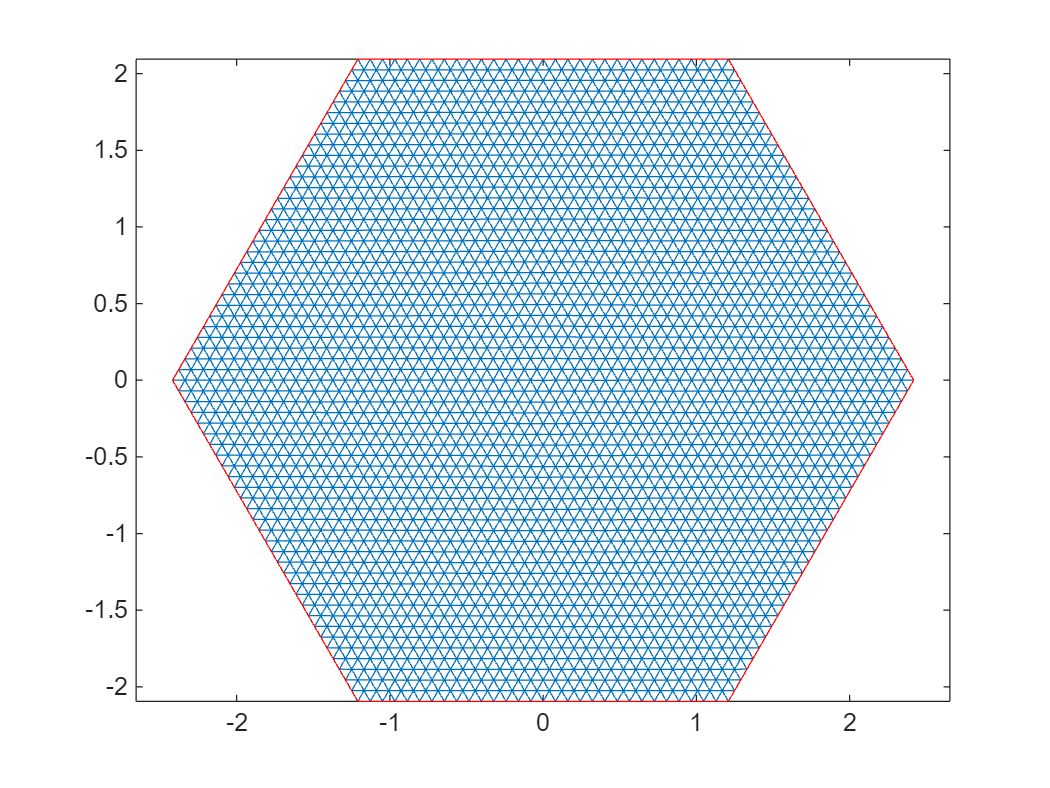

syst = Kane_mele_Model(lam_so = .05,lam_v = .1,lam_R = .06,Ns = 1);
mesh = TB_Hamilton.TopoNumber.FBZTri(syst,.08);
figure
pdeplot(mesh)

TB_Hamilton.TopoNumber.ChernByWilsonLoop(mesh,syst,2,"MultiBands")

ans = -1.7781e-16 - 1.2098e-15i

## Spin Hall Effect

Using the spin hall effect to demostrate the phase translation

sz = [1,0;0,-1];
Sz = kron(eye(2),sz); num = 50;
lam_Rs = linspace(-.5,.5,num); lam_vs = linspace(-.5,.5,num);
sigma = zeros(num);
tic
for j1 = 1:num
    for j2 = 1:num
        syst = Kane_mele_Model(lam_so = .06,lam_v = lam_vs(j2),lam_R = lam_Rs(j1),Ns = 1);
        kx = linspace(-pi/sqrt(3),pi/sqrt(3),400*.8);
        ky = linspace(0,4*pi/3,4*100);
        Omega = TB_Hamilton.TopoNumber.spin_curvature(syst,Sz,kx,ky,1:2);
        Omega1 = medfilt1(Omega','omitnan');
        sigma(j1,j2) = sum(Omega1(:))/(2*pi);
    end
end

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。


toc

figure
[Lam_R,Lam_v] = meshgrid(lam_Rs,lam_vs);

[KK2,EE2] = meshgrid(linspace(-.5,.5,500),linspace(-.5,.5,500));

V = interp2(Lam_R,Lam_v,sigma,EE2,KK2,'cubic');
contourf(KK2/0.06,EE2/0.06,V',256,'EdgeColor','none')
colormap(slanCM(104,256));

@author : slandarer


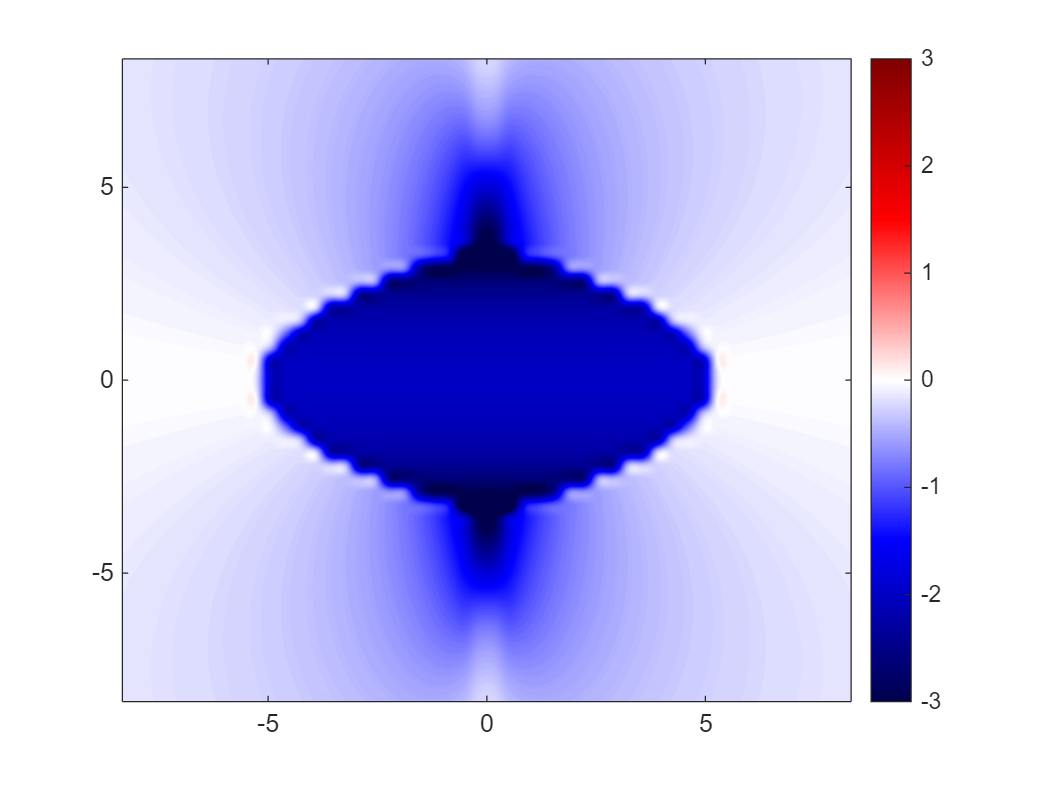

yticks([-5,0,5]);xticks([-5,0,5])
colorbar
clim([-3,3])
axis([-.5,.5,-.5,.5]/0.06)

syst = Kane_mele_Model(lam_so = .06,lam_v = .2,lam_R = .2,Ns = 1);
kx = linspace(-pi/sqrt(3),pi/sqrt(3),400*.8);
ky = linspace(0,4*pi/3,4*100);
Omega = TB_Hamilton.TopoNumber.spin_curvature(syst,Sz,kx,ky,0.211);
Omega1 = medfilt1(Omega','omitnan');
sum(Omega1(:))/(2*pi)

ans = -0.4142

figure
[Kx,Ky] = meshgrid(kx,ky);
contourf(Kx,Ky,Omega1,256,'EdgeColor','none')
colormap(slanCM(104,256));

@author : slandarer


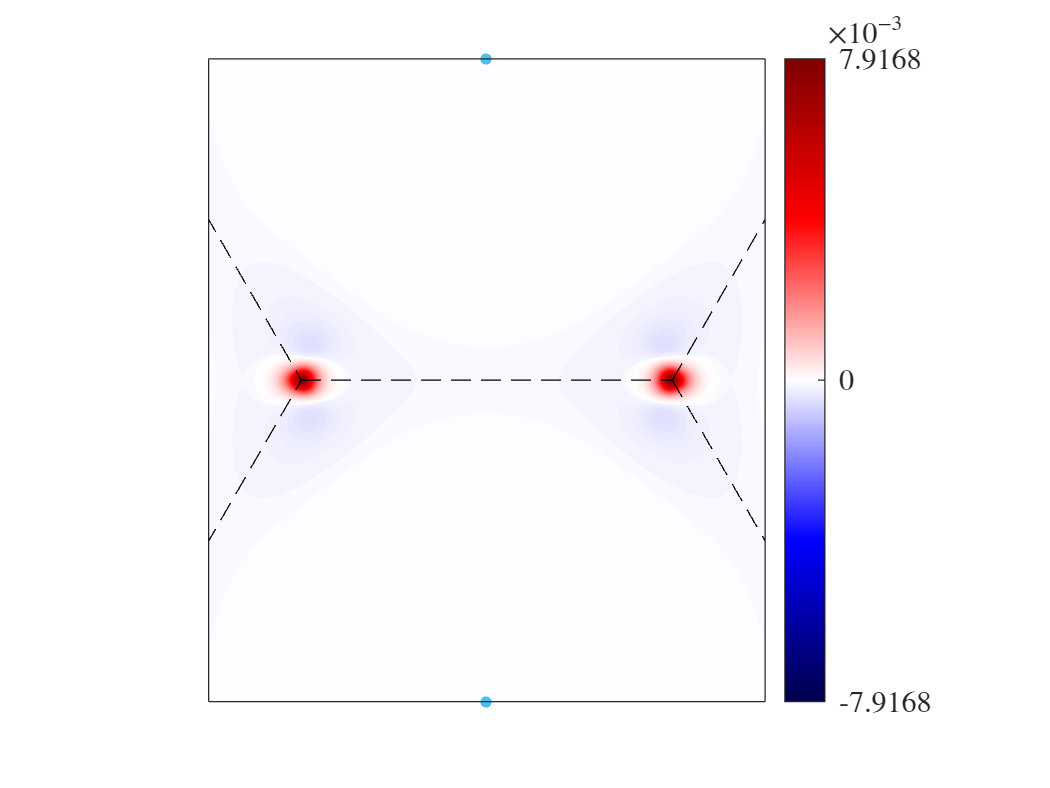

yticks([])
colorbar
hold on
TB_Hamilton.Plot.FBZ(syst)
axis([-pi/sqrt(3),pi/sqrt(3),0,4*pi/3])
clim_min = -max(abs(Omega1(:))); clim_max = max(abs(Omega1(:)));
clim([clim_min,clim_max]);
colorbar('Ticks',[clim_min,0,clim_max],'FontSize',12,'FontName','Times','TickLabelInterpreter','latex');

## Ribbon Band

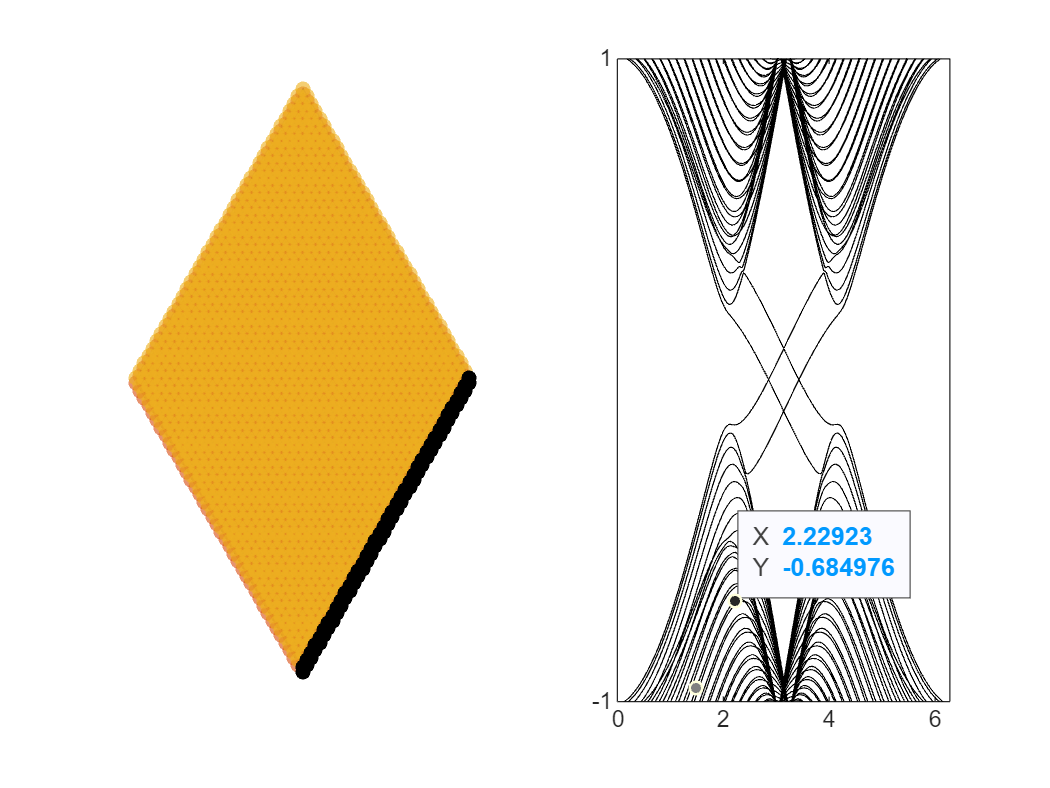

clear
syst = Kane_mele_Model(lam_so = .06,lam_v = .1,lam_R = 0.05,Ns = 10,Translation = [1,0]);
kx = linspace(0,2*pi,700); ky = 0; num = syst.system_graph.numnodes;
Es = zeros(num,length(kx));
for j1 = 1:length(kx)
    H = full(syst.Hamilton(kx(j1)));
    Es(:,j1) = eig(H);
end
tiledlayout(1,2)
nexttile
TB_Hamilton.Plot.ScatterRegion(syst)
axis off
nexttile
plot(kx,Es,'k')
ylim([-1,1])
yticks([-1,1]);xlim([0,2*pi])

## Spectral Function

k = linspace(0,2*pi,500);
Es = linspace(-1,1,500);
rho = zeros(length(Es),length(k));
SGF_k = TB_Hamilton.GreenFunction.SurfaceGF(syst,[0,-1]);
nk = length(k); nE = length(Es);
tic
parfor j1 = 1:nk
    k0 = k(j1);
    for j2 = 1:nE
        rho(j2,j1) = trace(SGF_k.SGF(Es(j2),k0));
    end
end
toc

历时 6.097903 秒。


[EE,KK] = meshgrid(Es,k);
% [KK2,EE2] = meshgrid(linspace(0,2*pi,500),linspace(-1,1,500));
rho1 = log(-(imag(rho)));
% V = interp2(EE,KK,rho1,EE2,KK2,'cubic');
% nexttile(t,2)
figure
contourf(KK,EE,rho1',256,'LineColor','none')
colormap(slanCM(104,256));

@author : slandarer


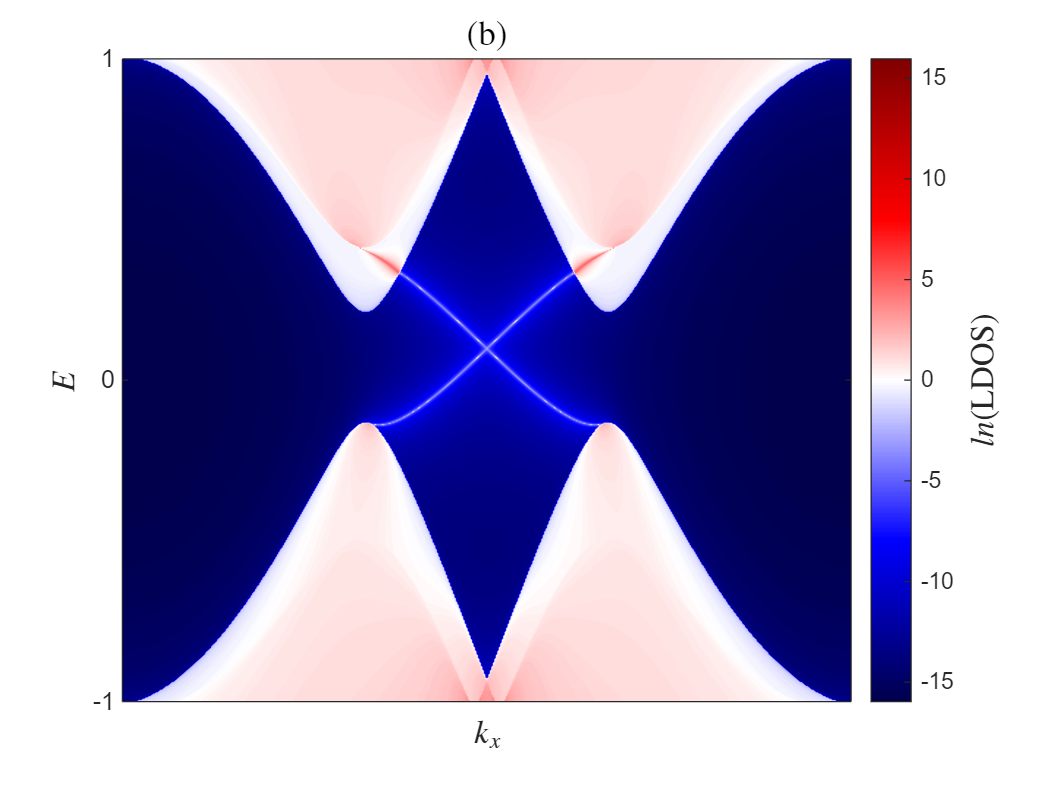

clim_max = max(abs(rho1(:))); clim_min = -clim_max;
clim([clim_min,clim_max])
c = colorbar;
c.Label.String = '$ln(\textrm{LDOS})$';
c.Label.Interpreter = 'latex';
c.Label.FontSize = 13;
xticks([]);xlabel('$k_x$','Interpreter','latex','FontSize',13);
yticks([-1,0,1])
ylabel('$E$','Interpreter','latex','FontSize',13);
title('$\textrm{(b)}$','FontSize',14,'Interpreter','latex')

## Local Density

syst = Kane_mele_Model(lam_so = .06,lam_v = .1,lam_R = 0.05,Ns = 10,Translation=[],disorder = .2);
GF = TB_Hamilton.GreenFunction.Green_Function(syst);
G = GF.GreenFunction(0,'method',3);
rho = -full(imag(diag(G)));

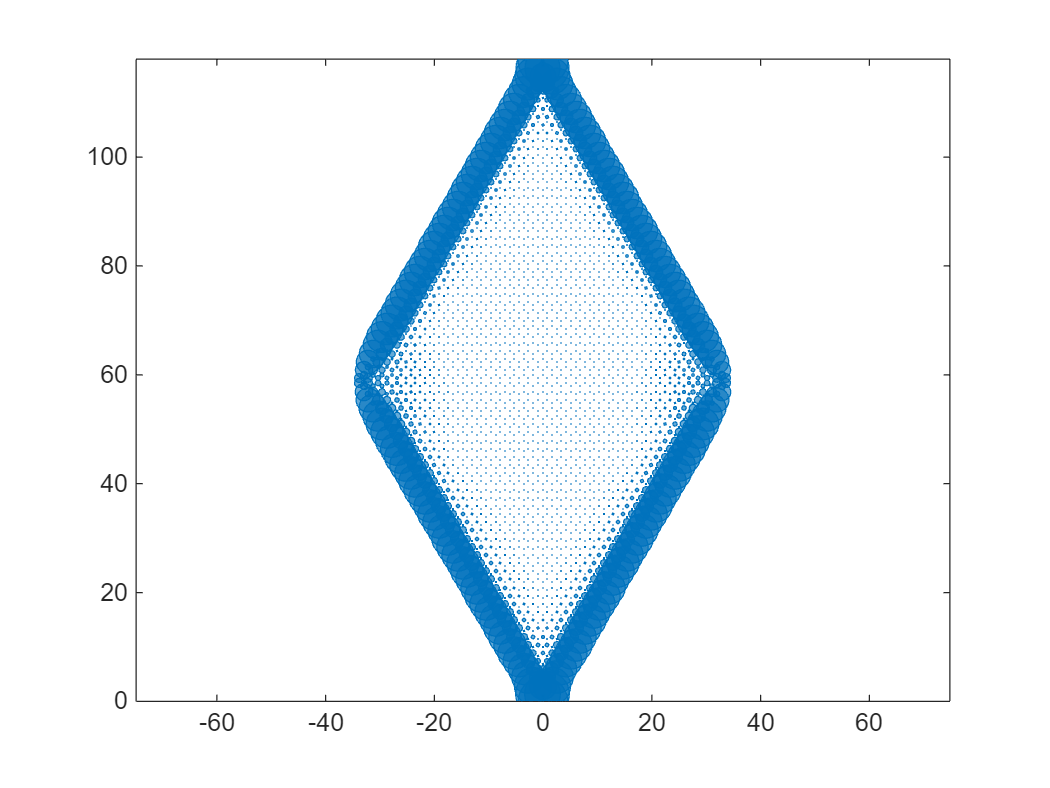

ans = 4×1 table
        Name    
    ____________

    {'A(3,3)_1'}
    {'A(3,3)_2'}
    {'B(3,3)_1'}
    {'B(3,3)_2'}


@author : slandarer


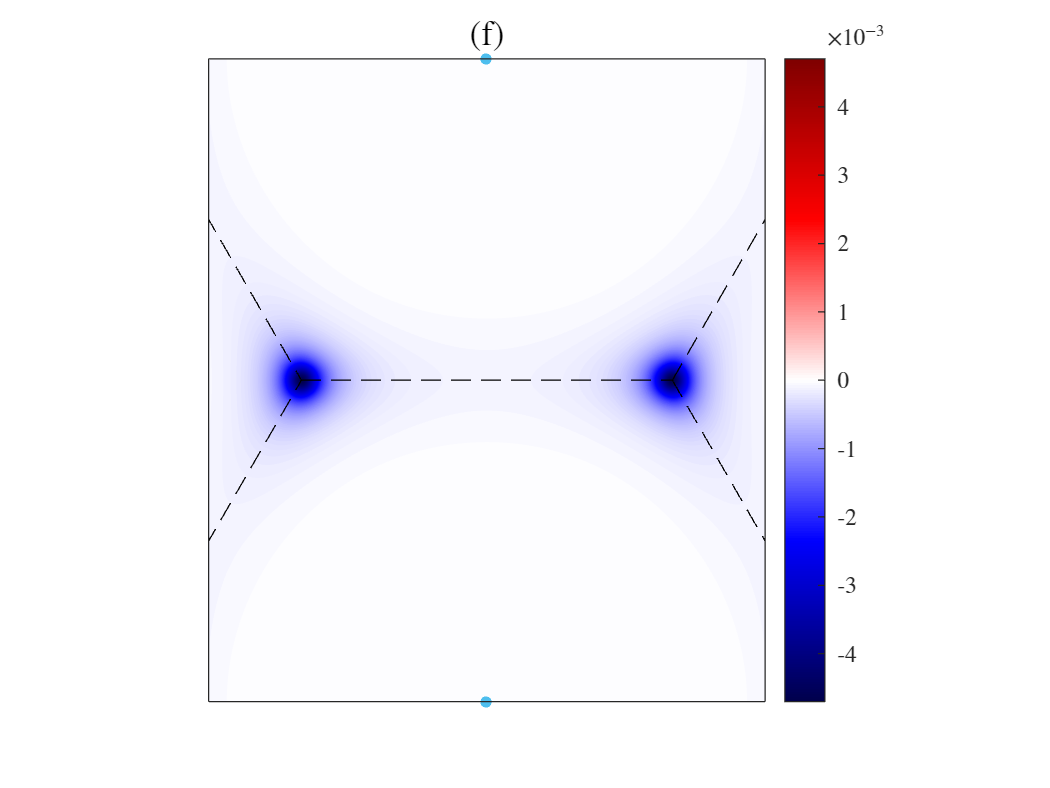

figure
pos = GF.GF_pos;
TB_Hamilton.Plot.Scatter(pos,rho/sum(rho));
bubblesize([.1 20])